# Principal Component Analysis (PCA)

*Pratheep Kumar Chelladurai*

Github Link: [https://github.com/pratheepkumar1/Principles-of-Color-Science/tree/main/Assignment%2014%20PCA](https://github.com/pratheepkumar1/Principles-of-Color-Science/tree/main/Assignment%2014%20PCA)

% Reading the Dataset
warning('off','all');
SGref_dataset = readtable("ccsg.xlsx");
SG_ref = SGref_dataset{:,5:end};
SGwl = (380:10:730)';

## Question 1

Use the Matlab function **pca** to compute 36 principal components of the CCSG. Make a plot of the first 5 principal components versus wavelength, and label them with a legend. Make a plot of the cumulative percentage of variance explained as a function of number of components.

% Compute the principal components of 36 wavelengths using PCA function
[coeff,score,latent,tsquared,explained,mu] = pca(SG_ref);

% Displaying the principal components
coeff

coeff =     0.0186   -0.0168   -0.0265    0.0261    0.0106    0.0625    0.2049    0.0798   -0.1617   -0.1484    0.1594   -0.2034   -0.3273    0.3605   -0.0306   -0.0427    0.2294    0.5374   -0.1555   -0.1111   -0.0107    0.1711    0.1653   -0.3055   -0.1939   -0.1346   -0.0524    0.0586   -0.0066   -0.0150   -0.0171    0.0022    0.0060   -0.0114   -0.0109   -0.0100
    0.0369   -0.0381   -0.0595    0.0593    0.0229    0.1101    0.3914    0.1457   -0.2981   -0.0961    0.1945   -0.1948   -0.3054    0.2267   -0.0035   -0.0838   -0.0065   -0.2055    0.0460    0.0588    0.0191   -0.1756   -0.2150    0.4364    0.2343    0.2760    0.1185   -0.1134   -0.0071    0.0220    0.0423   -0.0146   -0.0097    0.0263    0.0144    0.0175
    0.0768   -0.0840   -0.1186    0.1157    0.0704    0.0942    0.5497    0.1572   -0.2833    0.0855    0.0532    0.0805    0.1188   -0.2277    0.0661    0.0666   -0.2116   -0.3087    0.1575    0.0653   -0.0229    0.0424    0.1397   -0.2889   -0.1317   -0.3196   -0.1542

score

score =     3.3336   -0.4178   -0.0054    0.0044    0.0114   -0.0210   -0.0420   -0.0081    0.0175   -0.0057   -0.0026   -0.0041   -0.0019    0.0017   -0.0014    0.0001   -0.0010   -0.0019    0.0005    0.0004   -0.0001   -0.0003   -0.0000   -0.0001    0.0001    0.0001   -0.0000    0.0001   -0.0000   -0.0001   -0.0001   -0.0001   -0.0000   -0.0001   -0.0001    0.0001
   -0.7839   -0.2294   -0.0059    0.0849   -0.0062   -0.0125    0.0419    0.0101   -0.0082   -0.0070    0.0053   -0.0053   -0.0046    0.0033    0.0020    0.0004   -0.0003   -0.0005    0.0006   -0.0001   -0.0001   -0.0001    0.0001    0.0002    0.0001   -0.0001   -0.0000    0.0000   -0.0000    0.0001   -0.0000   -0.0001    0.0000    0.0001   -0.0000    0.0000
   -1.7847   -0.1292    0.0061    0.0545   -0.0137   -0.0170   -0.0269   -0.0053    0.0233   -0.0017   -0.0086    0.0006    0.0032   -0.0019   -0.0002   -0.0005   -0.0001    0.0002   -0.0002    0.0005    0.0001   -0.0002    0.0000   -0.0001    0.0001   -0.0001    0.0001

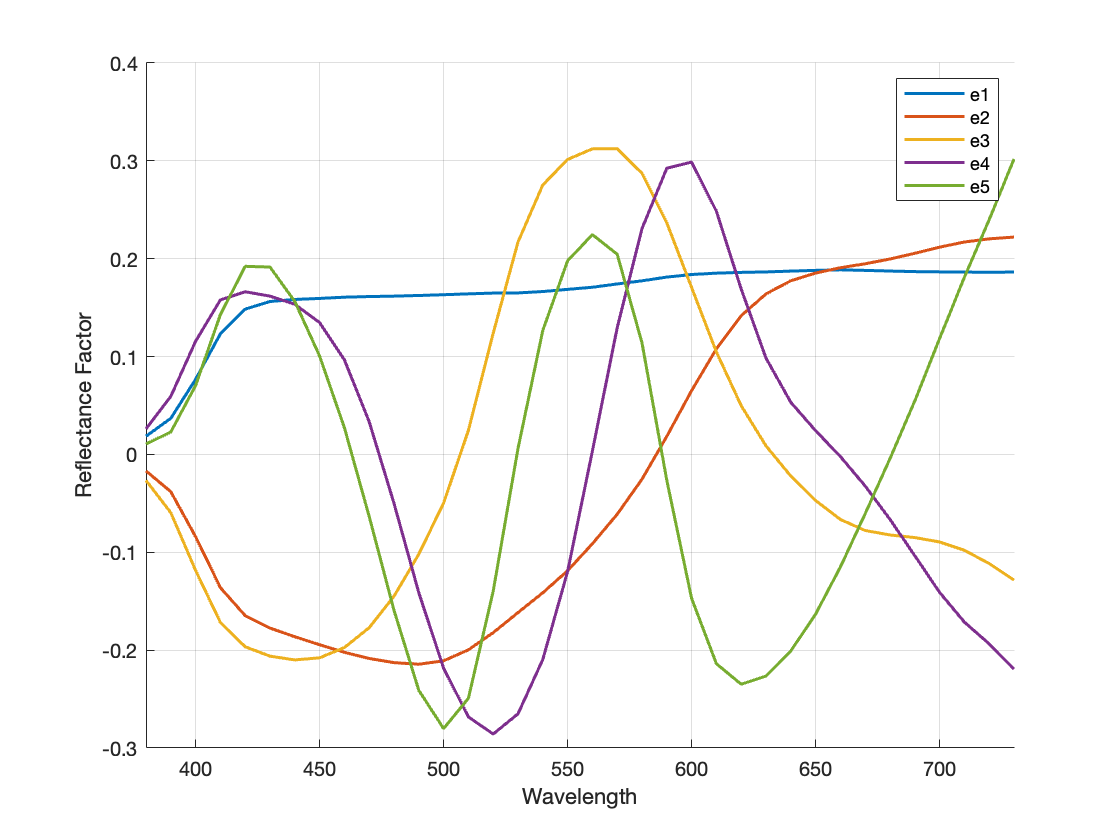


% Plot of the first 5 principal components versus wavelength
figure;
hold on
plot(SGwl,coeff(:,1:5),'LineWidth',1.5);
xlabel('Wavelength');
ylabel('Reflectance Factor');
xlim([380,730]);
legend("e1","e2","e3","e4","e5");
grid on
hold off

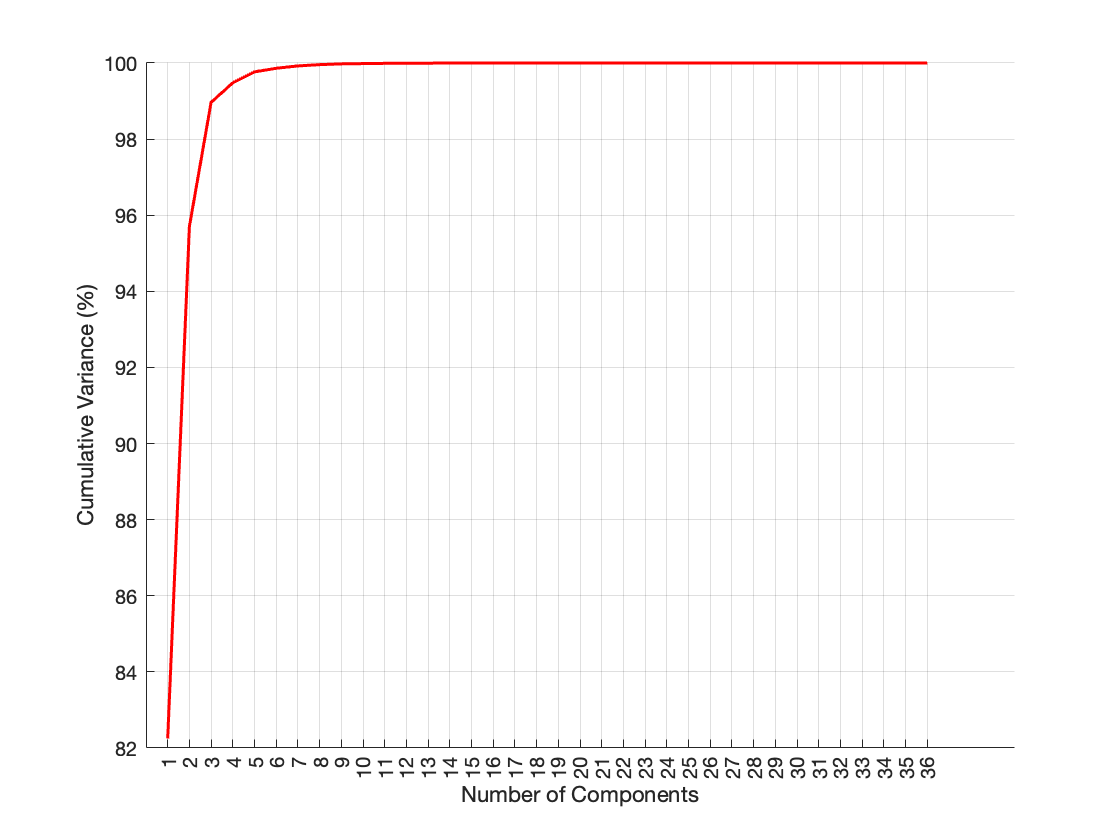

%Calculating & plotting cumulative percentage of the variance
cumsum_var = cumsum(latent);
cumsum_var_percent = (cumsum_var/cumsum_var(end,:))*100;

figure;
hold on
coeff_count = 1:1:36;
plot(coeff_count,cumsum_var_percent,'LineWidth',1.5,'Color','red');
xlabel('Number of Components');
ylabel('Cumulative Variance (%)');
xticks(1:1:36)
grid on
hold off

## Question 2

*Use the ****pca**** coefficients, scores, and mu (mean) to reconstruct the 140 spectra of CCSG patches. Confirm that they match.*

% Reconstruct the 140 spectra of CCSG patches
SG_reconst = score*coeff'+mu

SG_reconst =     0.1123    0.2108    0.4182    0.6675    0.8141    0.8639    0.8793    0.8872    0.8954    0.9000    0.9033    0.9072    0.9097    0.9114    0.9145    0.9145    0.9164    0.9175    0.9146    0.9160    0.9133    0.9129    0.9116    0.9102    0.9098    0.9093    0.9122    0.9152    0.9183    0.9166    0.9149    0.9142    0.9148    0.9161    0.9171    0.9222
    0.0619    0.1029    0.1506    0.1747    0.1812    0.1847    0.1876    0.1893    0.1894    0.1884    0.1877    0.1872    0.1873    0.1876    0.1884    0.1882    0.1883    0.1884    0.1888    0.1908    0.1916    0.1920    0.1911    0.1897    0.1879    0.1856    0.1839    0.1822    0.1808    0.1789    0.1770    0.1752    0.1737    0.1722    0.1703    0.1689
    0.0118    0.0123    0.0121    0.0119    0.0119    0.0119    0.0118    0.0117    0.0117    0.0115    0.0116    0.0116    0.0116    0.0113    0.0113    0.0112    0.0113    0.0113    0.0112    0.0112    0.0110    0.0111    0.0111    0.0110    0.0109    0.0108    0

%Confirm if reconstruct match
isequal(fi(SG_ref),fi(SG_reconst))

ans = logical
   1


Yes, the reconstructed spectral data matches with the original CCSG spectral data. For the comparison, both the matrices are converted from real numbers to fixed point data type. Because, real numbers have infinite precision and will be difficult to compare.

## Question 3

*Use only the first ****pca**** coefficient (vector) with the mu to reconstruct the 140 CCSG patches. Compute the DE00 color difference (for 2-deg observer under D65 illuminant) between the original and reconstructed; report the mean and max DE00. *

% Compute CCSG reference LAB values for De00 calcualtion
[num,txt] = xlsread('all_1nm_data.xlsx');
cmf2 = interp1(num(:,1),num(:,6:8),SGwl);
D65 = interp1(num(:,1),num(:,3),SGwl);
SGXYZ_ref = ((cmf2' * diag(D65) * SG_ref') ./ (cmf2(:,2)' * D65) )';
SGLab_ref = xyz2lab(SGXYZ_ref);

% Reconstructed CCSG data with 1st PCA coefficient
SG_reconst_first = score(:,1)*coeff(:,1)'+mu

SG_reconst_first =     0.1171    0.2169    0.4132    0.6259    0.7373    0.7737    0.7865    0.7946    0.8034    0.8099    0.8156    0.8214    0.8276    0.8362    0.8459    0.8504    0.8572    0.8653    0.8723    0.8867    0.9033    0.9263    0.9450    0.9583    0.9684    0.9758    0.9839    0.9907    0.9970    0.9980    0.9986    0.9998    1.0030    1.0068    1.0086    1.0153
    0.0407    0.0649    0.0970    0.1183    0.1260    0.1303    0.1344    0.1382    0.1417    0.1456    0.1495    0.1526    0.1556    0.1606    0.1671    0.1709    0.1719    0.1707    0.1689    0.1694    0.1728    0.1802    0.1880    0.1955    0.2025    0.2079    0.2125    0.2163    0.2204    0.2237    0.2270    0.2306    0.2350    0.2392    0.2426    0.2477
    0.0221    0.0280    0.0202   -0.0051   -0.0226   -0.0261   -0.0241   -0.0213   -0.0191   -0.0159   -0.0124   -0.0099   -0.0077   -0.0036    0.0021    0.0057    0.0053    0.0019   -0.0021   -0.0050   -0.0048   -0.0012    0.0040    0.0101    0.0163    0.021


% Compute CCSG 1st PCA coefficient data's LAB values
SGXYZ_reconst_first = ((cmf2' * diag(D65) * SG_reconst_first') ./ ...
    (cmf2(:,2)' * D65) )';
SGLab_reconst_first = xyz2lab(SGXYZ_reconst_first);

% DE00 color difference between the original and reconstructed
De00_first = deltaE00(SGLab_reconst_first',SGLab_ref');

% De00 mean
De00_first_mean = mean(De00_first)

De00_first_mean = 18.4574


% De00 Max Value
De00_first_max = max(De00_first)

De00_first_max = 39.5881

## Question 4

*Reconstruct the 140 CCSG patches with the first two ****pca**** coefficients, and report mean and max DE00.*

% Reconstructed CCSG data with first two PCA coefficient
SG_reconst_second = score(:,1:2)*coeff(:,1:2)'+mu

SG_reconst_second =     0.1241    0.2328    0.4483    0.6828    0.8062    0.8479    0.8643    0.8758    0.8879    0.8970    0.9045    0.9110    0.9157    0.9196    0.9220    0.9180    0.9163    0.9149    0.9104    0.9122    0.9138    0.9186    0.9178    0.9132    0.9092    0.9072    0.9098    0.9132    0.9173    0.9166    0.9151    0.9140    0.9145    0.9161    0.9166    0.9225
    0.0446    0.0736    0.1163    0.1495    0.1638    0.1710    0.1772    0.1828    0.1881    0.1934    0.1983    0.2018    0.2040    0.2064    0.2089    0.2080    0.2043    0.1980    0.1898    0.1834    0.1786    0.1759    0.1731    0.1707    0.1699    0.1703    0.1718    0.1738    0.1766    0.1790    0.1812    0.1835    0.1864    0.1894    0.1920    0.1968
    0.0243    0.0329    0.0311    0.0125   -0.0013   -0.0032    0.0000    0.0038    0.0071    0.0111    0.0151    0.0178    0.0195    0.0222    0.0256    0.0266    0.0235    0.0173    0.0097    0.0029   -0.0015   -0.0036   -0.0044   -0.0038   -0.0021    0.00


% Compute CCSG 2nd PCA coefficient data's LAB values
SGXYZ_reconst_second = ((cmf2' * diag(D65) * SG_reconst_second') ./ ...
    (cmf2(:,2)' * D65) )';
SGLab_reconst_second = xyz2lab(SGXYZ_reconst_second);

% DE00 color difference between the original and reconstructed
De00_second = deltaE00(SGLab_reconst_second',SGLab_ref');

% De00 mean
De00_second_mean = mean(De00_second)

De00_second_mean = 14.3649


% De00 Max Value
De00_second_max = max(De00_second)

De00_second_max = 44.1072

## Bonus

*Keep going with this series, and determine how many ****pca**** coefficients are necessary to reduce the max DE00 below 0.5.*

% Determine number of pca coefficients to reduce the max DE00 below 0.5.
for i = 1:36
    SG_reconst_f = score(:,1:i)*coeff(:,1:i)'+mu; 
    SGXYZ_reconst_f = ((cmf2' * diag(D65) * SG_reconst_f') ./ ...
        (cmf2(:,2)' * D65) )';
    SGLab_reconst_f = xyz2lab(SGXYZ_reconst_f);
    De00_f = deltaE00(SGLab_reconst_f',SGLab_ref');
    De00_f_max = max(De00_f);
    if(De00_f_max <= 0.5)
        disp("Number of coefficients to minimize De00 below 0.5 is " + i)
        disp("The De00 value at " + i + "th coefficient is " + De00_f_max);
        break;
    end
end

Number of coefficients to minimize De00 below 0.5 is 11


The De00 value at 11th coefficient is 0.34552


## Functions

function   De00=deltaE00(Lab1, Lab2)

%CIELAB Chroma
C1 = sqrt(Lab1(2,:).^2+Lab1(3,:).^2);
C2 = sqrt(Lab2(2,:).^2+Lab2(3,:).^2);

%Lab Prime
mC = (C1+C2)./2;
G=0.5*(1-sqrt((mC.^7)./((mC.^7)+(25.^7))));
LabP1 = [Lab1(1,:) ; Lab1(2,:).*(1+G) ; Lab1(3,:)];
LabP2 = [Lab2(1,:) ; Lab2(2,:).*(1+G) ; Lab2(3,:)];

%Chroma
CP1 = sqrt(LabP1(2,:).^2+LabP1(3,:).^2);
CP2 = sqrt(LabP2(2,:).^2+LabP2(3,:).^2);

%Hue Angle
hP1t = atan2Deg(LabP1(3,:),LabP1(2,:));
hP2t = atan2Deg(LabP2(3,:),LabP2(2,:));

%Add in 360 to the smaller hue angle if absolute value of difference is > 180
hP1 = hP1t + ((hP1t<hP2t)&(abs(hP1t-hP2t)>180)).*360;
hP2 = hP2t + ((hP1t>hP2t)&(abs(hP1t-hP2t)>180)).*360;

%Delta Values
DLP = LabP1(1,:) - LabP2(1,:);
DCP = CP1 - CP2;
DhP = hP1 - hP2;
DHP = 2*(CP1.*CP2).^(1/2).*sinDeg(DhP./2);

%Arithmetic mean of LCh' values
mLP = (LabP1(1,:)+LabP2(1,:))./2;
mCP = (CP1+CP2)./2;
mhP = (hP1+hP2)./2;

%Weighting Functions
SL = 1+(0.015.*(mLP-50).^2)./sqrt(20+(mLP-50).^2);
SC = 1+0.045.*mCP;
T = 1-0.17.*cosDeg(mhP-30)+0.24.*cosDeg(2.*mhP)+0.32.* ...
    cosDeg(3.*mhP+6)-0.2.*cosDeg(4.*mhP-63);
SH = 1+0.015.*mCP.*T;

%Rotation function
RC = 2.*sqrt((mCP.^7)./((mCP.^7)+25.^7));
DTheta = 30.*exp(-((mhP-275)./25).^2);
RT = -sinDeg(2.*DTheta).*RC;

%Parametric factors
kL = 1;
kC = 1;
kH = 1;

De00 = ((DLP./kL./SL).^2+(DCP./kC./SC).^2+(DHP./kH./SH).^2+...
    (RT.*(DCP./kC./SC).*(DHP./kH./SH))).^(1/2);

end

%--------------
function out = sinDeg(in);
out = sin(in.*pi./180);
end

%--------------
function out = cosDeg(in);
out = cos(in.*pi./180);
end

%--------------
function out = atan2Deg(inY,inX);
out = atan2(inY,inX).*180./pi;
out = out+(out<0).*360;

end
